clearvars
u = symunit;

syms d turnsRatio
format shortEng
% format short
v_o = 48

v_o =     48.0000e+000



d_min = 0.278; v_d_minduty = 18;
d_max = 0.366; v_d_maxduty = 12

v_d_maxduty =     12.0000e+000



turnsRatio_minduty = ( (d_min/(1-d_min)) * (v_d_minduty/v_o) )^-1

turnsRatio_minduty =      6.9257e+000


turnsRatio_maxduty = ( (d_max/(1-d_max)) * (v_d_maxduty/v_o) )^-1

turnsRatio_maxduty =      6.9290e+000


U_o = v_o;
v_t = d_max;
f_sw = 100e3;
i_out = 1;
i_avgSec = i_out/(1-v_t);
xformerCurrRipple = 0.5; % percent
L_sec = (U_o*(1-v_t))/(xformerCurrRipple*i_avgSec*f_sw)

L_sec =    385.8778e-006



L_pri = L_sec/(turnsRatio_maxduty^2)

L_pri =      8.0374e-006


% (turnsRatio_maxduty^2)*2.814e-6

syms priTurns secTurns
AL = 51e-9 % nH/T^2; minimal

AL =     51.0000e-009


priTurns = double(solve(L_pri == AL*priTurns^2))

priTurns =    -12.5537e+000
    12.5537e+000


secTurns = double(solve(L_sec == AL*secTurns^2))

secTurns =    -86.9841e+000
    86.9841e+000


% make sure core is not saturated
ampTurns = i_out*secTurns

ampTurns =    -86.9841e+000
    86.9841e+000


**AWG selection**

p_o = i_out * v_o

p_o =     48.0000e+000


i_in_max = v_o/v_d_maxduty

i_in_max =      4.0000e+000


selectedAWGRating = 0.226;
num_of_paralles_sec = i_out/selectedAWGRating

num_of_paralles_sec =      4.4248e+000


num_of_paralles_pri = i_in_max/selectedAWGRating

num_of_paralles_pri =     17.6991e+000


**Fill Factor Calculation**

windowArea_mm2 = 427;
priTurns = ceil(priTurns(priTurns>0))

priTurns =     13.0000e+000


secTurns = ceil(secTurns(secTurns>0))

secTurns =     87.0000e+000


num_of_paralles_pri = ceil(num_of_paralles_pri)

num_of_paralles_pri =     18.0000e+000


num_of_paralles_sec = ceil(num_of_paralles_sec)

num_of_paralles_sec =      5.0000e+000



cableArea_mm2 = 0.080;

primaryArea_mm2 = priTurns*num_of_paralles_pri*cableArea_mm2

primaryArea_mm2 =     18.7200e+000


secondaryArea_mm2 = secTurns*num_of_paralles_sec*cableArea_mm2

secondaryArea_mm2 =     34.8000e+000


totalCableArea_mm2 = primaryArea_mm2 + secondaryArea_mm2

totalCableArea_mm2 =     53.5200e+000


fillFactor_perc = 100*totalCableArea_mm2/windowArea_mm2

fillFactor_perc =     12.5340e+000


**Cable Resistance Calculation**

windingLengthPerTurn_mm = 68.2

windingLengthPerTurn_mm =     68.2000e+000


ohms_per_meter = 212.872 / 1e3

ohms_per_meter =    212.8720e-003


primaryLength_m = windingLengthPerTurn_mm * priTurns * 1e-3

primaryLength_m =    886.6000e-003


secondaryLength_m = windingLengthPerTurn_mm * secTurns * 1e-3

secondaryLength_m =      5.9334e+000



primary_DC_resistance_ohm = ohms_per_meter * primaryLength_m / num_of_paralles_pri

primary_DC_resistance_ohm =     10.4851e-003


secondary_DC_resistance_ohm = ohms_per_meter * secondaryLength_m / num_of_paralles_sec

secondary_DC_resistance_ohm =    252.6109e-003


**Copper Loss Calculation**

diameter_mm = vpa(0.32004*u.mm)

$$diameter\_mm = 0.32004\,\mathrm{mm}$$

radius_mm = diameter_mm/2

$$radius\_mm = 0.16002\,\mathrm{mm}$$

skinDepth_cm = vpa(7.5/sqrt(f_sw)*u.cm)

$$skinDepth\_cm = 0.023717082451262844989991701583245\,\mathrm{cm}$$

skinDepth_mm = unitConvert(skinDepth_cm, u.mm)

$$skinDepth\_mm = 0.23717082451262844989991701583245\,\mathrm{mm}$$

% skin depth is greater than radius.
% Therefore, AC reistance equals DC resistance
DC_to_AC_ratio = 1

DC_to_AC_ratio =      1.0000e+000


primary_AC_resistance_ohm = primary_DC_resistance_ohm*DC_to_AC_ratio

primary_AC_resistance_ohm =     10.4851e-003


secondary_AC_resistance_ohm = secondary_DC_resistance_ohm*DC_to_AC_ratio

secondary_AC_resistance_ohm =    252.6109e-003



resistancePri_ohm = vpa(primary_AC_resistance_ohm * u.Ohm)

$$resistancePri\_ohm = 0.010485128622222223207516300647058\,\Omega$$

resistanceSec_ohm = vpa(secondary_AC_resistance_ohm * u.Ohm)

$$resistanceSec\_ohm = 0.25261094496000002784796834021108\,\Omega$$

copperLossPri = vpa(unitConvert((i_in_max*u.A)^2 * resistancePri_ohm, u.W))

$$copperLossPri = 0.16776205795555557132026081035292\,W$$

copperLossSec = vpa(unitConvert((i_out*u.A)^2 * resistanceSec_ohm, u.W))

$$copperLossSec = 0.25261094496000002784796834021108\,W$$


copperLoss_W = copperLossPri + copperLossSec

$$copperLoss\_W = 0.420373002915555599168229150564\,W$$

**Core Loss Calculation**

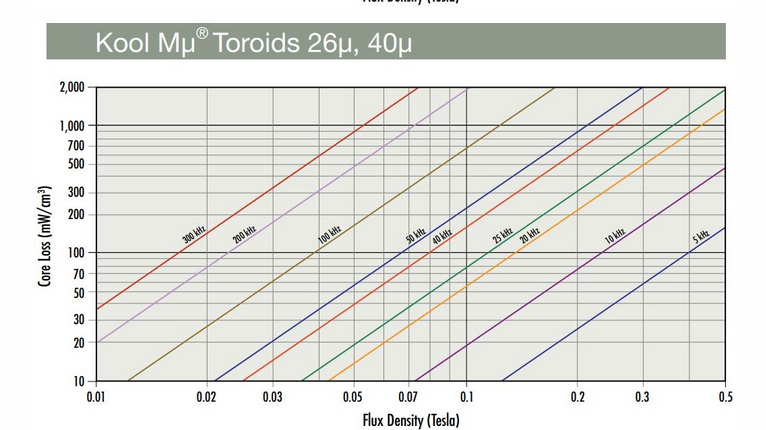

permeability = 26;
mu_zero = 1.25663706212e-6;
pathLength_m = 107e-3;
fluxDensity_Tesla = mu_zero * permeability * ampTurns / pathLength_m

fluxDensity_Tesla =    -26.5607e-003
    26.5607e-003


% using graph above, 0.03 Tesla @ 100 kHz corresponds to
wattLoss_mW_cm3 = 60*u.mW/u.cm^3

$$wattLoss\_mW\_cm3 = 60\,\frac{\mathrm{mW}}{{\mathrm{cm}}^{3}}$$

volume_mm3 = 21300;
volume_cm3 = vpa(unitConvert(volume_mm3*u.mm^3, u.cm^3))

$$volume\_cm3 = 21.3\,{\mathrm{cm}}^{3}$$

coreLoss_w = vpa(unitConvert(wattLoss_mW_cm3 * volume_cm3, u.W))

$$coreLoss\_w = 1.278\,W$$